# LME Tutorial 4: Within- and between-subject factors

## Global parameters

clear % clear workspace
close all % close figures
% seed = 'shuffle'; % random seed
seed = 0;
rng(seed); % set random seed
N_m = 100; % number of male subjects
N_f = 150; % number of female subjects
DFMethod = 'satterthwaite';
% DFMethod = 'residual';

## Influence of Chocolate and Gender on long jump

Distance without chocolate, male subjects

N = N_m;
Distance_m_0_true = 7.76 + 0.36*randn(N,1);
Distance_m_0 = Distance_m_0_true + 0.01*randn(N,1);

Distance with chocolate, male subjects

Distance_m_1 = Distance_m_0_true + 0.01 + 0.01*randn(N,1);

Female subjects

N = N_f;
Distance_f_0_true = 6.42 + 0.34*randn(N,1);
Distance_f_0 = Distance_f_0_true + 0.01*randn(N,1);
Distance_f_1 = Distance_f_0_true - 0.01 + 0.01*randn(N,1);

Histogram male

cmap = colormap('lines');
h1 = histfit(Distance_m_0);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Distance_m_1);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'without','with'})
hold off

Histogram female

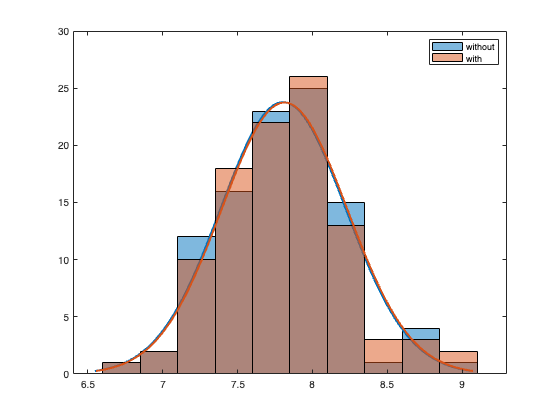

cmap = colormap('lines');

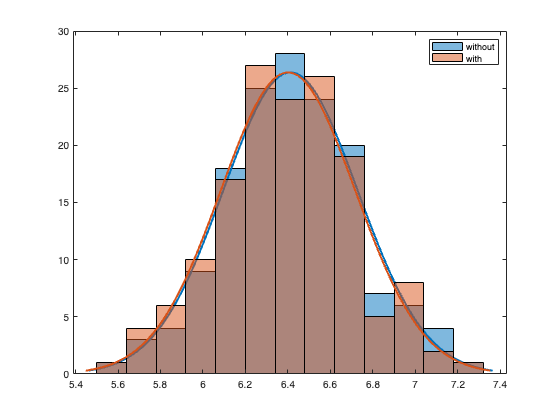

h1 = histfit(Distance_f_0);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Distance_f_1);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'without','with'})
hold off

## Create Datasets

N = N_m;
Subject1 = categorical((1:N)');
Chocolate1 = repmat({'without'},N,1);
Subject2 = categorical((1:N)');
Chocolate2 = repmat({'with'},N,1);
Subject_m = [Subject1;Subject2];
Chocolate_m = [Chocolate1;Chocolate2];
Distance_m = [Distance_m_0;Distance_m_1];
Gender_m = repmat({'male'},2*N,1);

N = N_f;
Subject1 = categorical(N_m + (1:N)');
Chocolate1 = repmat({'without'},N,1);
Subject2 = categorical(N_m + (1:N)');
Chocolate2 = repmat({'with'},N,1);
Subject_f = [Subject1;Subject2];
Chocolate_f = [Chocolate1;Chocolate2];
Distance_f = [Distance_f_0;Distance_f_1];
Gender_f = repmat({'female'},2*N,1);

Subject = [Subject_m;Subject_f];
Chocolate = [Chocolate_m;Chocolate_f];
Distance = [Distance_m;Distance_f];
Gender = [Gender_m;Gender_f];

% create table
Data = table;
Data.Subject = categorical(Subject);
Data.Gender = categorical(Gender);
Data.Chocolate = categorical(Chocolate);
Data.Distance = Distance;
% sort by subject
Data = sortrows(Data,{'Subject'});
head(Data)

ans = 8×4 table
    Subject    Gender    Chocolate        Distance    
    _______    ______    _________    ________________

       1        male      without     7.96196392553413
       1        male      with        7.96539244286661
       2        male      without     8.41131828443094
       2        male      with        8.41990092981857
       3        male      without     6.94781605837008
       3        male      with           6.96630734835
       4        male      without     8.06493710603262
       4        male      with        8.08345301452399


% save data table to Excel file
writetable(Data,'Chocolate_LM4.xlsx', 'WriteMode', 'replacefile');

## T-test

male

[~,p_unpaired] = ttest2(Distance_m_0,Distance_m_1)

p_unpaired =    0.871404835582852


[~,p_paired] = ttest(Distance_m_0,Distance_m_1)

p_paired =      1.383996003055012e-08


female

[~,p_unpaired] = ttest2(Distance_f_0,Distance_f_1)

p_unpaired =    0.753691886200365


[~,p_paired] = ttest(Distance_f_0,Distance_f_1)

p_paired =      1.771411812470189e-21


both

[~,p_unpaired] = ttest2([Distance_m_0;Distance_f_0],[Distance_m_1;Distance_f_1])

p_unpaired =    0.964884561130396


[~,p_paired] = ttest([Distance_m_0;Distance_f_0],[Distance_m_1;Distance_f_1])

p_paired =    0.005498269056622


## ANOVA

1-way ANOVA

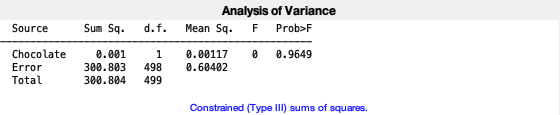

ans =    0.964884561130401


anovan(Distance,{Chocolate},'varnames',{'Chocolate'})

2-way ANOVA with Subject as (dummy) factor

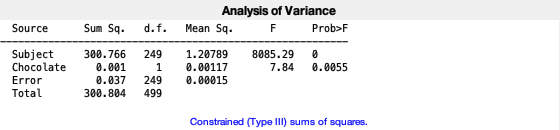

ans =                    0
   0.005498269057439


anovan(Distance,{Subject,Chocolate},'varnames',{'Subject','Chocolate'})

3-way ANOVA with Subject as (dummy) factor

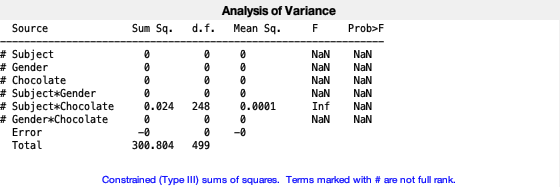

ans =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


anovan(Distance,{Subject,Gender,Chocolate},'model','interaction','varnames',{'Subject','Gender','Chocolate'})

2-way ANOVA without Subject as (dummy) factor

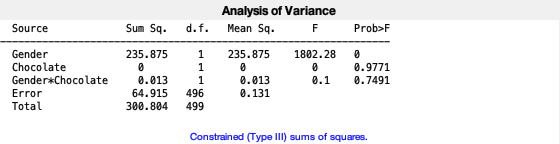

ans =    0.000000000000000
   0.977100696521668
   0.749117280827619


anovan(Distance,{Gender,Chocolate},'model','interaction','varnames',{'Gender','Chocolate'})

## Linear model

## Null model

formula = 'Distance ~ 1'

formula = 'Distance ~ 1'

mdl0 = fitlme(Data,formula);
anova(mdl0,'DFMethod',DFMethod)

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                   FStat               DF1    DF2                 pValue
    {'(Intercept)'}        40343.2976578557    1      500.000009513313    0     


## Half model (without gender)

formula = 'Distance ~ 1 + Chocolate + (1|Subject)'

formula = 'Distance ~ 1 + Chocolate + (1|Subject)'

mdl1 = fitlme(Data,formula);
anova(mdl1,'DFMethod',DFMethod)

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                   FStat               DF1    DF2                 pValue               
    {'(Intercept)'}        20163.2080528986    1      250.445914686625    2.38694025598472e-241
    {'Chocolate'  }        7.87564676985266    1      250.380909169575      0.00540439554386637


Goodness of fit

mdl = mdl1;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.999876288531606


Plot residuals

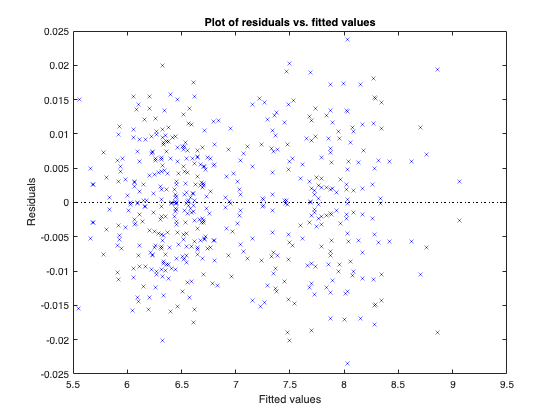

plotResiduals(mdl,'fitted');

Plot partial dependence

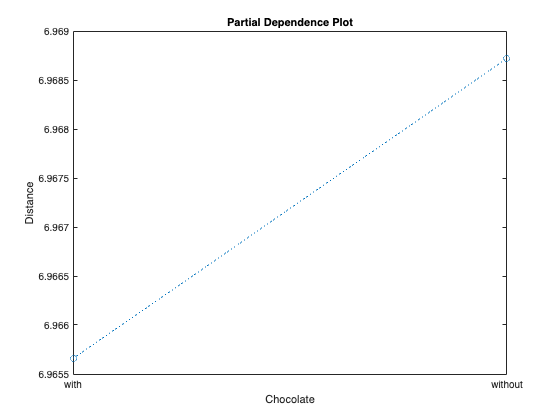

plotPartialDependence(mdl,'Chocolate')

## Full model (with gender)

formula = 'Distance ~ Chocolate * Gender + (1|Subject)'

formula = 'Distance ~ Chocolate * Gender + (1|Subject)'

mdl2a = fitlme(Data,formula);
anova(mdl2a,'DFMethod',DFMethod)

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                        FStat               DF1    DF2                 pValue               
    {'(Intercept)'     }        47333.5128339759    1      250.281398892431    3.19122786585277e-287
    {'Gender'          }        922.160397922976    1       250.27164775853     6.73562337479348e-86
    {'Chocolate'       }        104.477070327613    1      250.075522216431     1.01591881750445e-20
    {'Gender:Chocolate'}        140.762475580221    1      250.075522217812     4.71187582376066e-26


Goodness of fit

mdl = mdl2a;
RSquared = mdl.Rsquared.Ordinary

RSquared =    0.999920840617971


Plot residuals

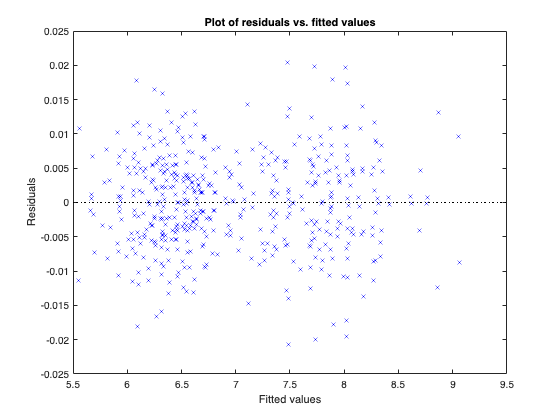

plotResiduals(mdl,'fitted');

Plot partial dependence

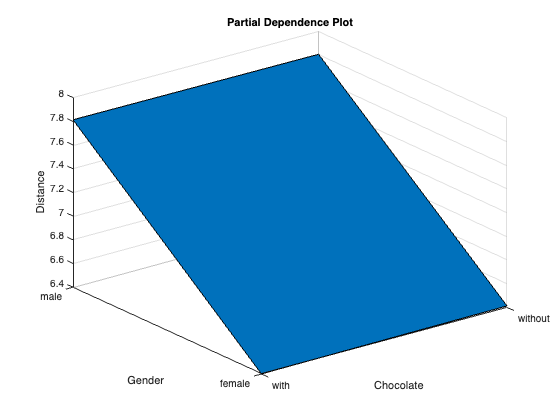

plotPartialDependence(mdl,{'Chocolate','Gender'})

## Change from dummy coding (reference coding)  to deviation coding (effect coding)

formula = 'Distance ~ 1 + Chocolate*Gender + (1|Subject)'

formula = 'Distance ~ 1 + Chocolate*Gender + (1|Subject)'

mdl2b = fitlme(Data,formula,'DummyVarCoding','effects')

mdl2b = Linear mixed-effects model fit by ML

Model information:
    Number of observations             500
    Fixed effects coefficients           4
    Random effects coefficients        250
    Covariance parameters                2

Formula:
    Distance ~ 1 + Gender*Chocolate + (1 | Subject)

Model fit statistics:
    AIC                  BIC                  LogLikelihood       Deviance         
    -1221.14389494981    -1195.85624635928    616.571947474904    -1233.14389494981

Fixed effects coefficients (95% CIs):
    Name                                    Estimate                SE                      tStat                DF     pValue                   Lower                   Upper               
    {'(Intercept)'                 }            7.10738959573214       0.023254049397333     305.640943402627    496                        0        7.06170100955993        7.15307818190435
    {'

anova(mdl2b,'DFMethod',DFMethod)

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                        FStat               DF1    DF2                 pValue               
    {'(Intercept)'     }        93416.3862840476    1      250.038019398833    9.88131291682493e-324
    {'Gender'          }        908.748074086039    1       250.03802031589     3.10810897125309e-85
    {'Chocolate'       }        1.13386054290399    1      250.036309103601        0.287980577858239
    {'Gender:Chocolate'}        140.762469808528    1      250.036309103601     4.72000449944179e-26


## Compare models

compare(mdl0,mdl1)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik               LRStat              deltaDF    pValue
    mdl0     2      1168.86412640683     1177.29334260367    -582.432063203414                                         
    mdl1     4     -730.076573951746    -713.218141558057     369.038286975873    1902.94070035857    2          0     


compare(mdl1,mdl2a)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue
    mdl1     4     -730.076573951746    -713.218141558057    369.038286975873                                         
    mdl2a    6     -1221.14389495001    -1195.85624635948    616.571947475005    495.067320998264    2          0     


compare(mdl2a,mdl2b)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat                   deltaDF    pValue
    mdl2a    6     -1221.14389495001    -1195.85624635948    616.571947475005                                              
    mdl2b    6     -1221.14389494981    -1195.85624635928    616.571947474904    -2.01680450118147e-10    0          0     


## Look at the fit results

display(mdl1)

mdl1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             500
    Fixed effects coefficients           2
    Random effects coefficients        250
    Covariance parameters                2

Formula:
    Distance ~ 1 + Chocolate + (1 | Subject)

Model fit statistics:
    AIC                  BIC                  LogLikelihood       Deviance         
    -730.076573951746    -713.218141558057    369.038286975873    -738.076573951746

Fixed effects coefficients (95% CIs):
    Name                         Estimate               SE                     tStat               DF     pValue                 Lower                   Upper              
    {'(Intercept)'      }           6.96565790551279     0.0490548922442673    141.997211426488    498                      0        6.86927784641522       7.06203796461037
    {'Chocolate_without'}        0.0030618796717

display(mdl2b)

mdl2b = Linear mixed-effects model fit by ML

Model information:
    Number of observations             500
    Fixed effects coefficients           4
    Random effects coefficients        250
    Covariance parameters                2

Formula:
    Distance ~ 1 + Gender*Chocolate + (1 | Subject)

Model fit statistics:
    AIC                  BIC                  LogLikelihood       Deviance         
    -1221.14389494981    -1195.85624635928    616.571947474904    -1233.14389494981

Fixed effects coefficients (95% CIs):
    Name                                    Estimate                SE                      tStat                DF     pValue                   Lower                   Upper               
    {'(Intercept)'                 }            7.10738959573214       0.023254049397333     305.640943402627    496                        0        7.06170100955993        7.15307818190435
    {'